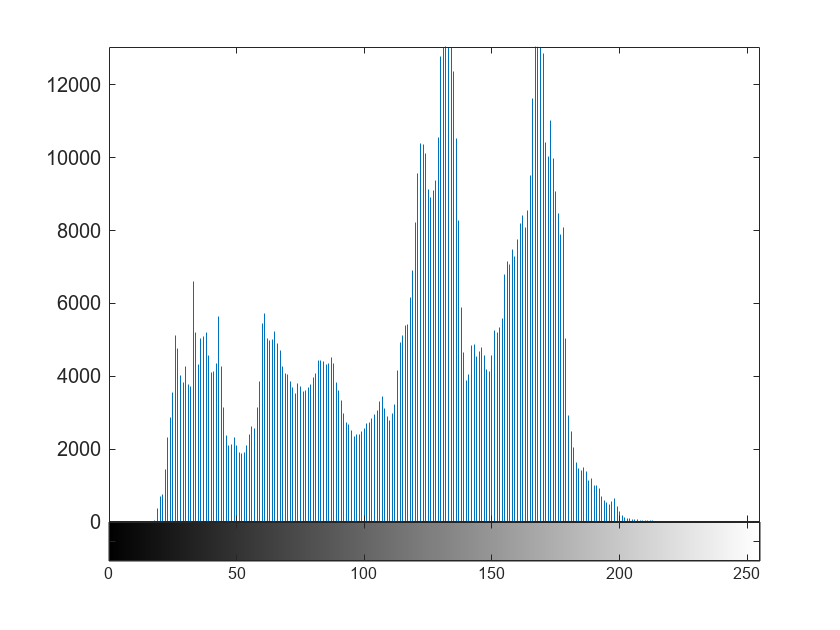

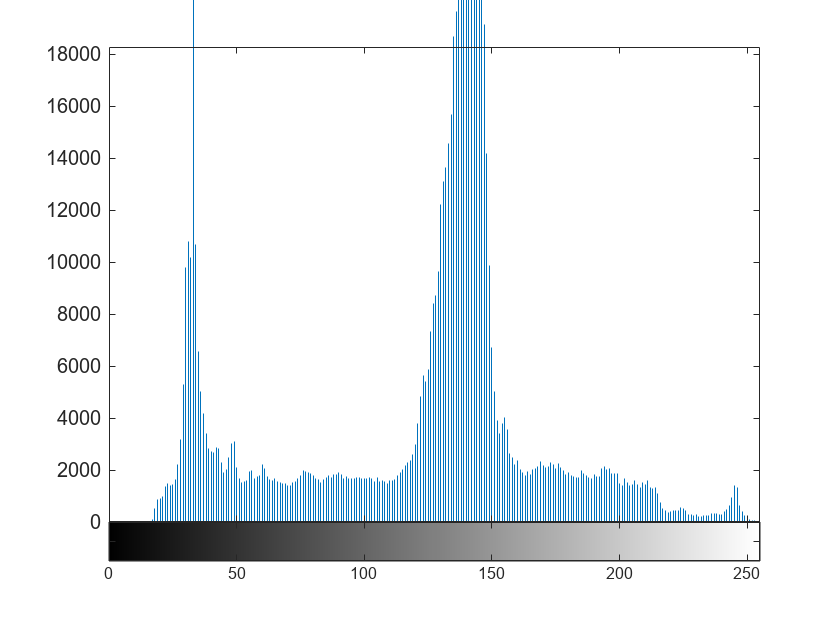

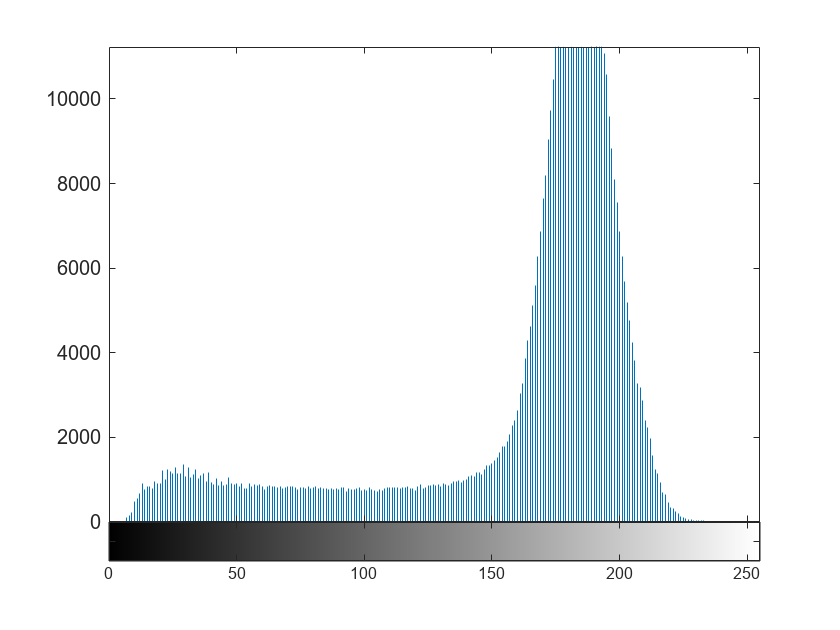

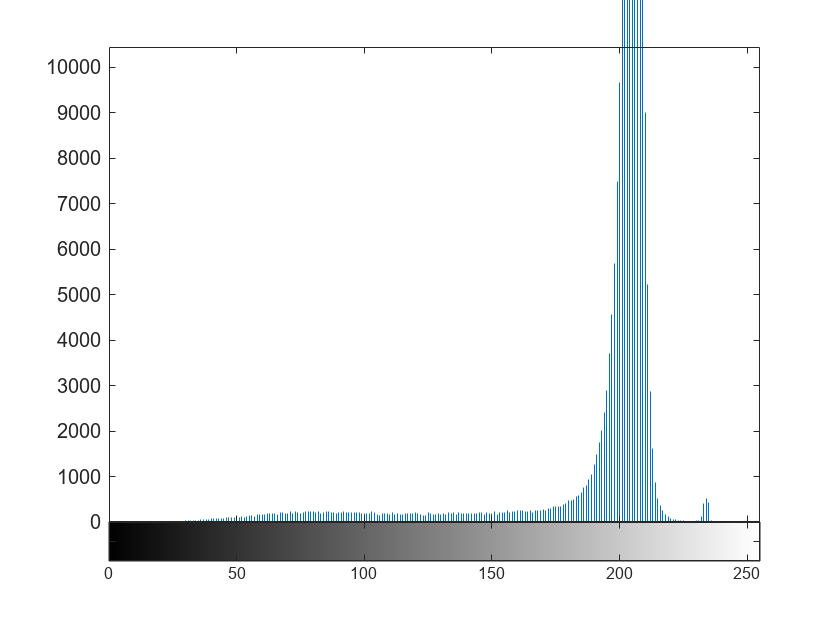

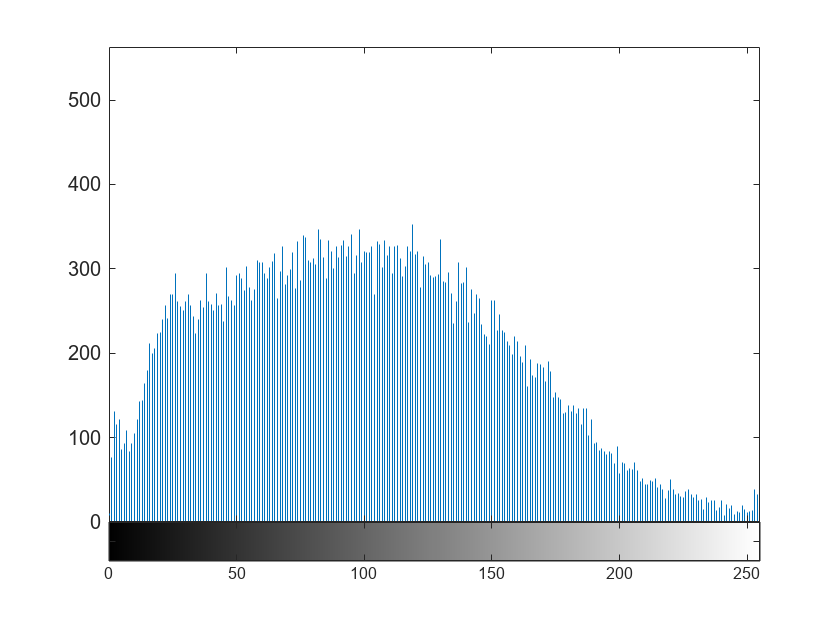

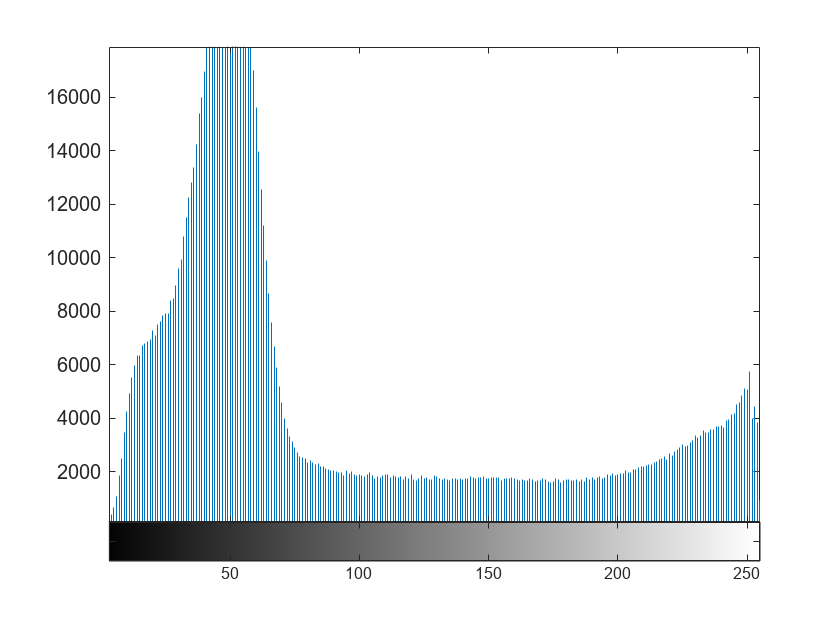

path_one = "C:\Users\atche\OneDrive\Documents\MATLAB\EE146\Images\WIN_20230201_22_09_10_Pro.jpg";
path_two = "C:\Users\atche\OneDrive\Documents\MATLAB\EE146\Images\WIN_20230201_22_10_00_Pro.jpg";
path_three = "C:\Users\atche\OneDrive\Documents\MATLAB\EE146\Images\constitution.jpg";
path_four = "C:\Users\atche\OneDrive\Documents\MATLAB\EE146\Images\hancock.jpg";
path_five = "C:\Users\atche\OneDrive\Documents\MATLAB\EE146\Images\texturedIMG1.jfif";
path_six = "C:\Users\atche\OneDrive\Documents\MATLAB\EE146\Images\texturedIMG2.jpg";

numImg = uint8(6);
I_mich = imread(path_one);
I_mil = imread(path_two);
I_const = imread(path_three);
I_husky = imread(path_four);
I_text_one = imread(path_five);
I_text_two = imread(path_six);

imgGray_arr = {I_mich, I_mil, I_const, I_husky, I_text_one, I_text_two};

for i = 1:numImg
    imgGray_arr{i} = im2gray(imgGray_arr{i});
    figure
    %imshow(imgGray_arr{i}) 
    imhist(imgGray_arr{i})
end

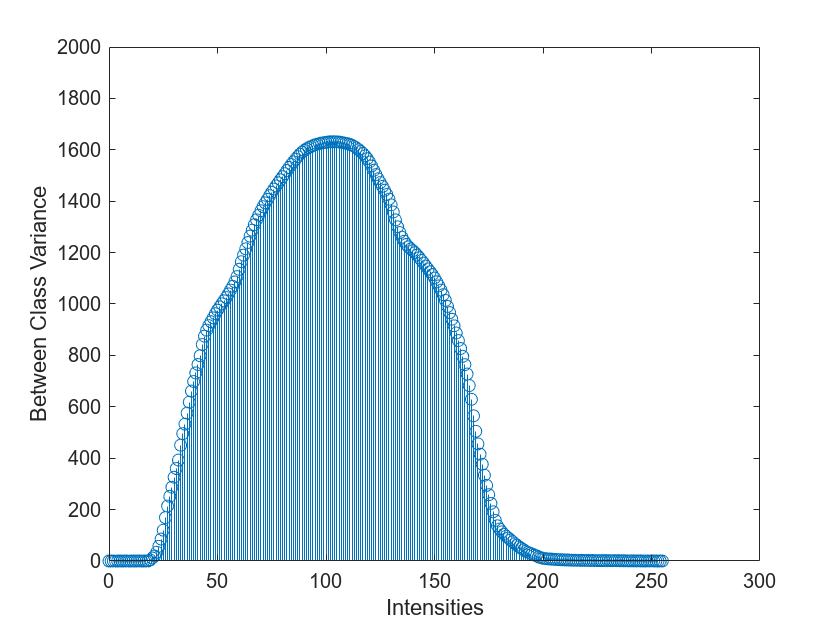

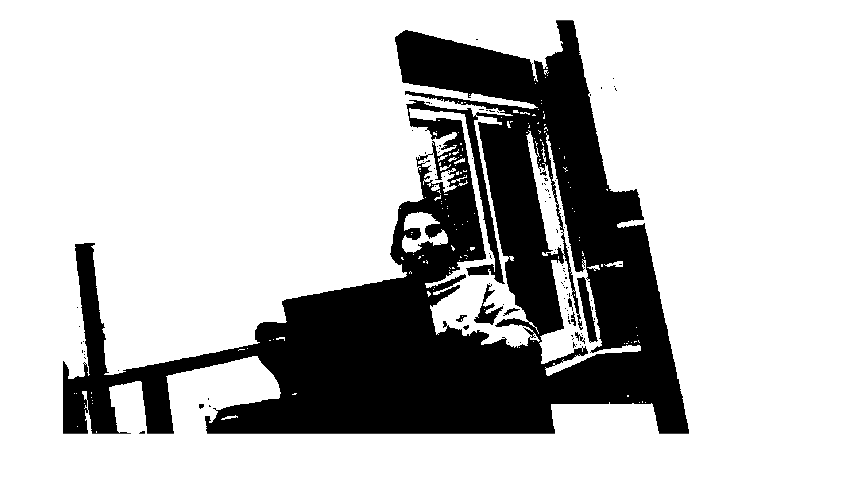

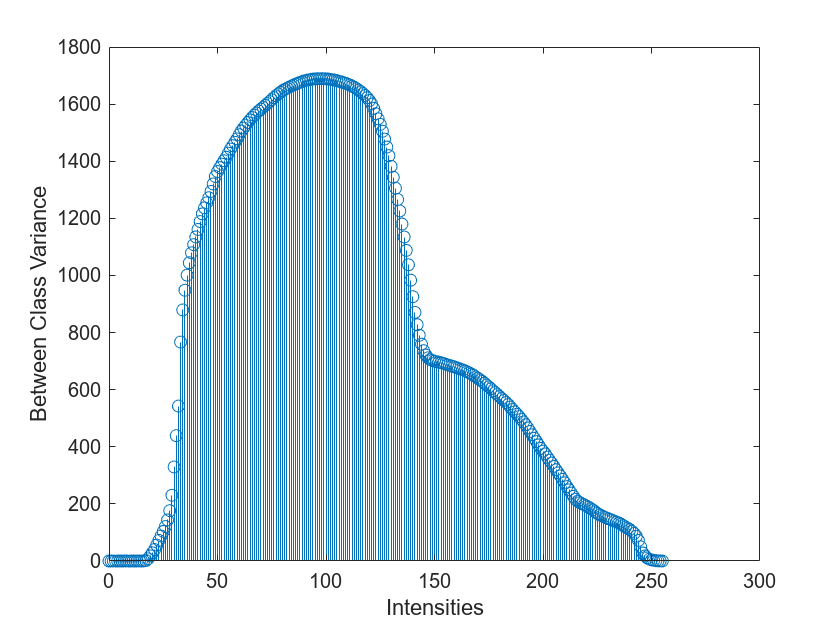

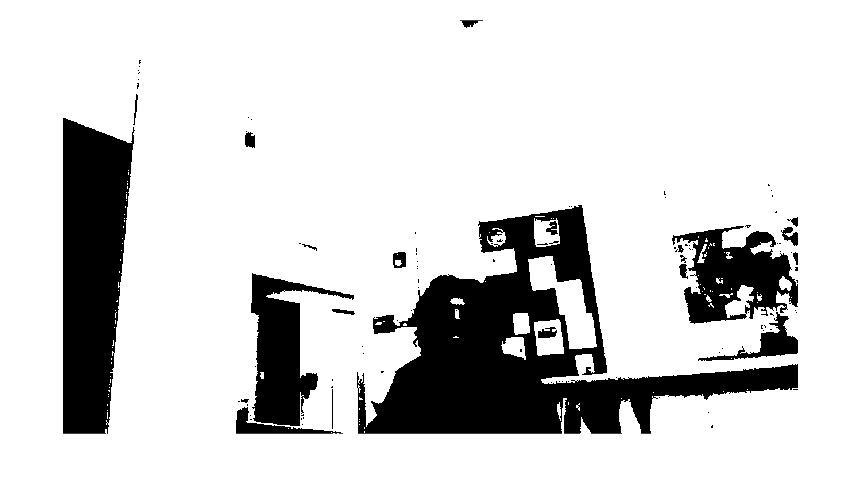

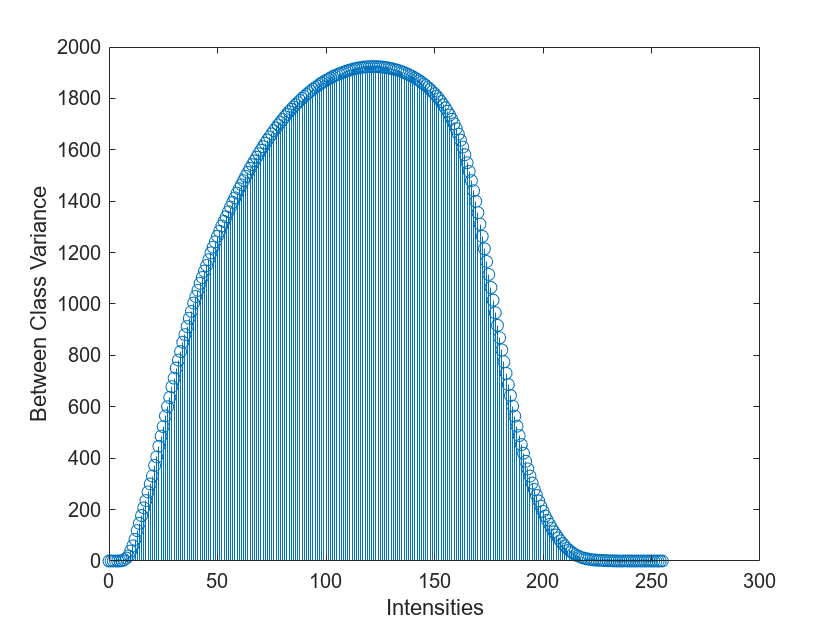

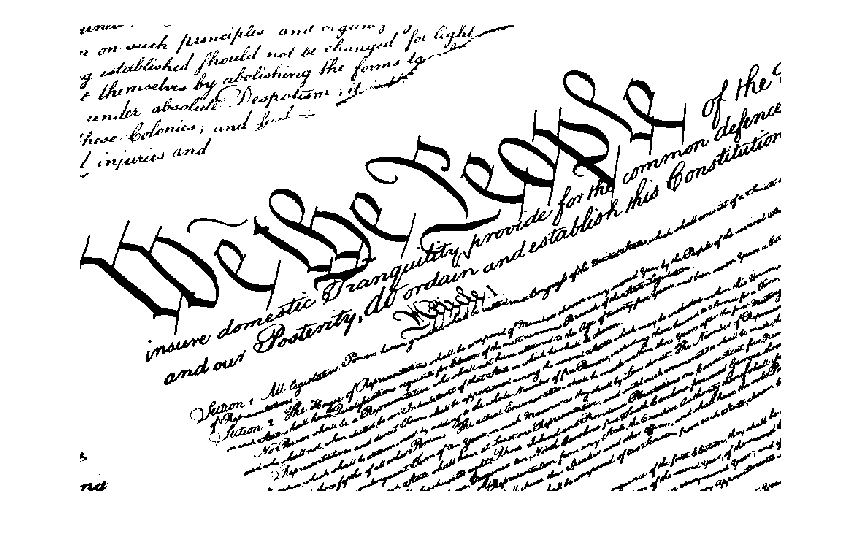

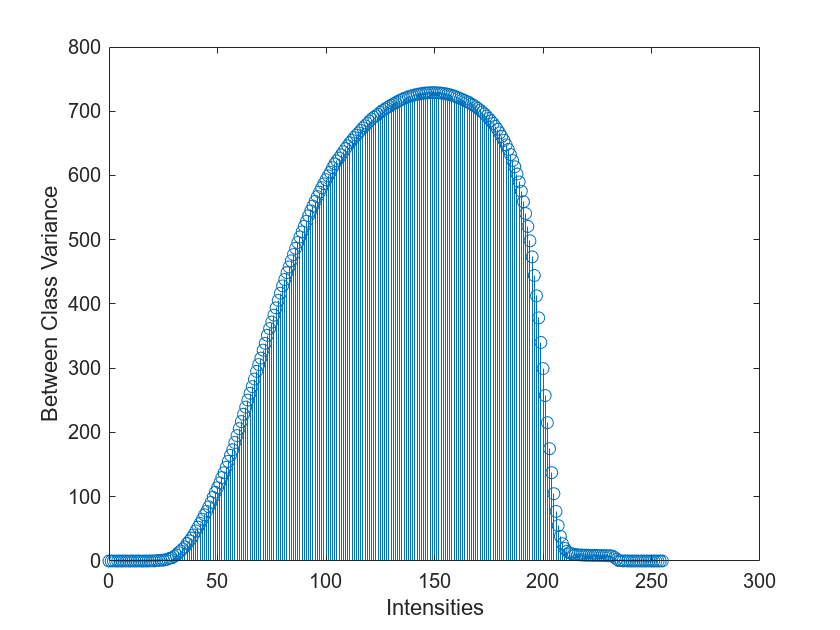

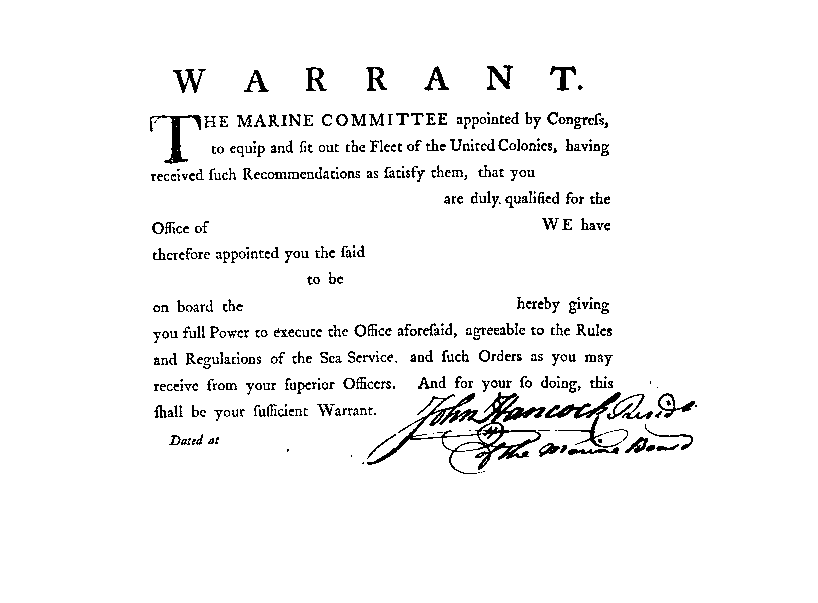


T_arr = zeros(numImg,1);

for i = 1:numImg
    bcv_curr = zeros(256,1);
    T_arr(i) = otsu_thresh(imgGray_arr{i}, bcv_curr);
    bw = imbinarize(imgGray_arr{i},T_arr(i)); 
    figure
    imshow(bw)
end

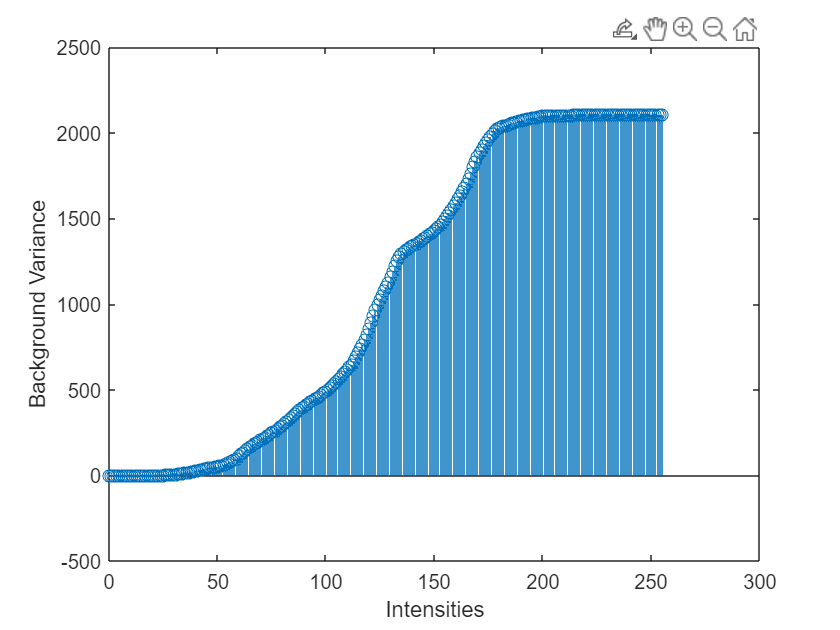

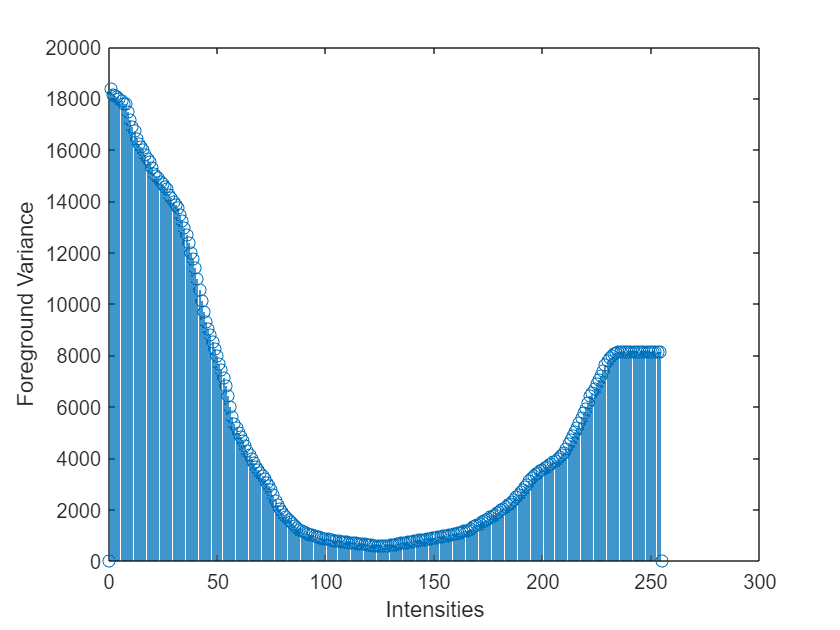

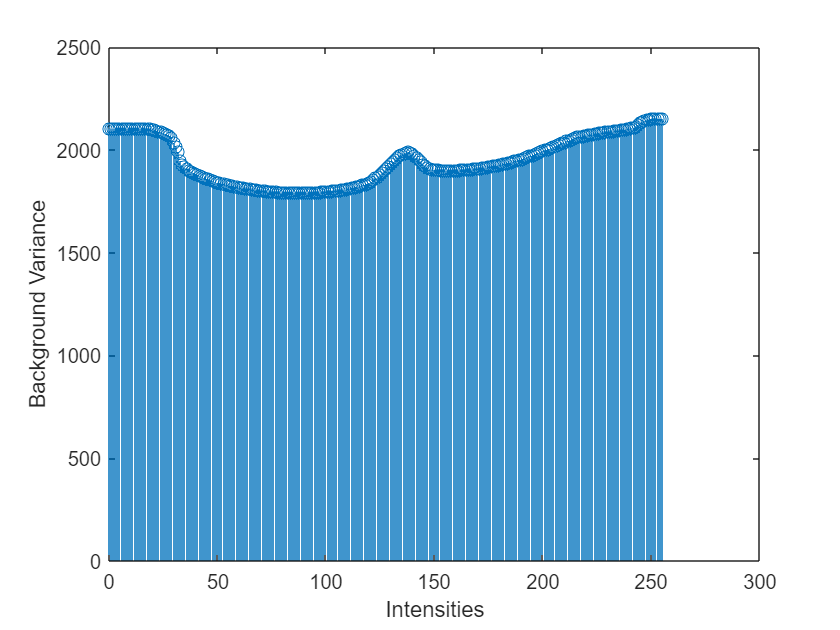

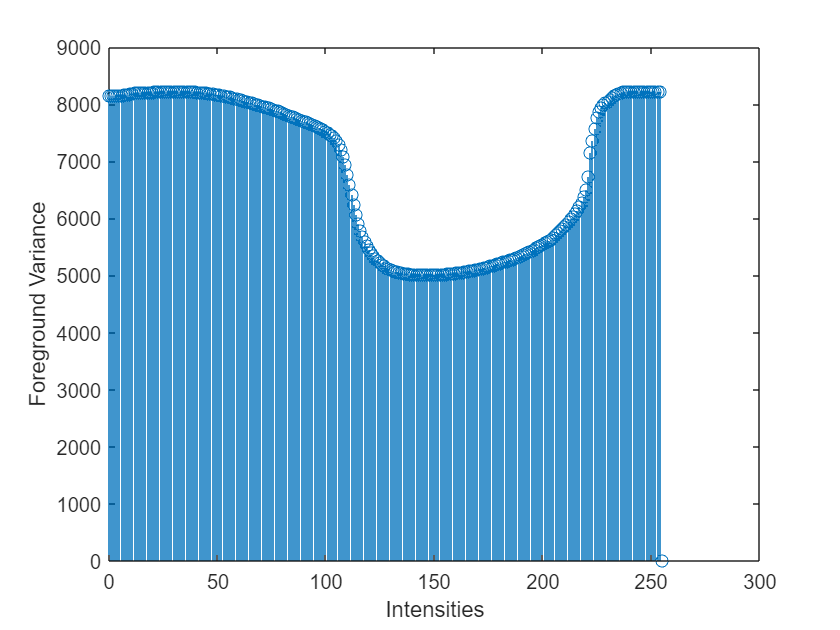

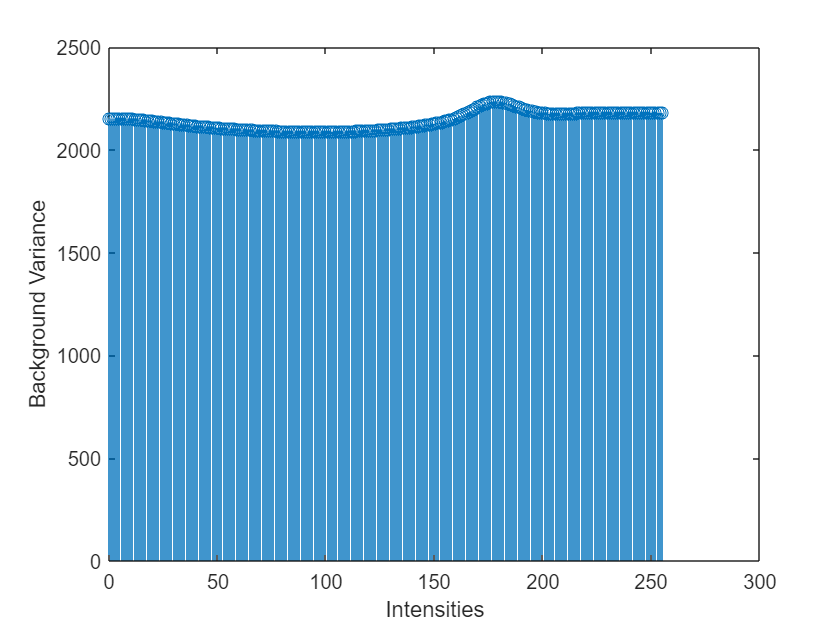

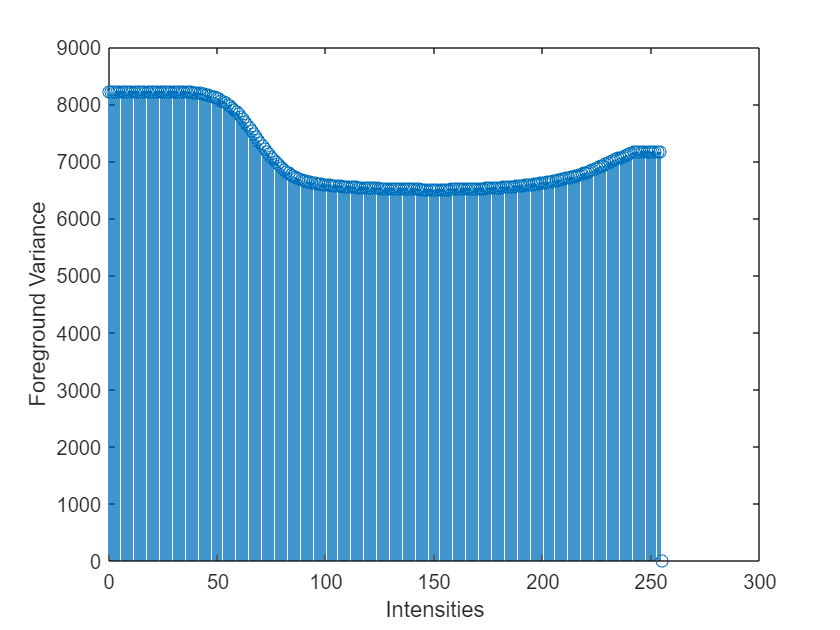

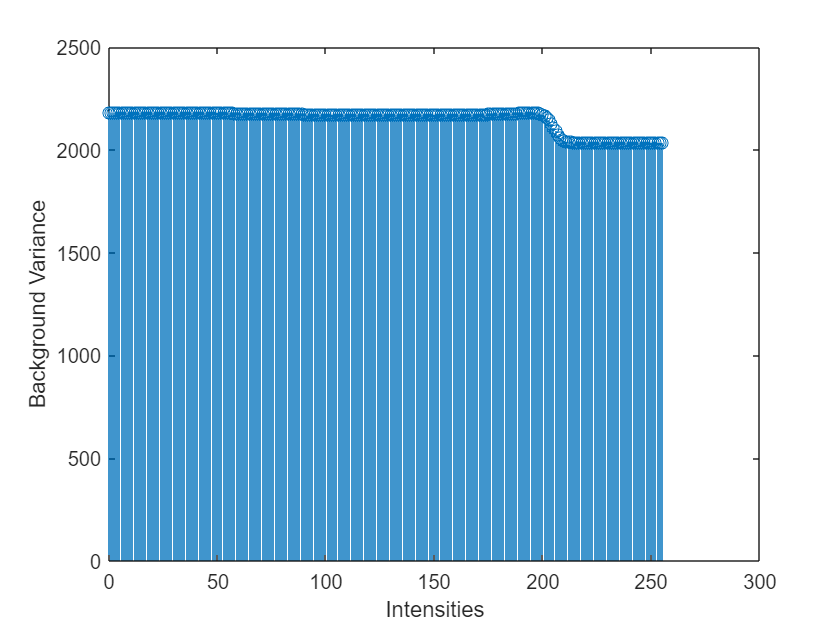

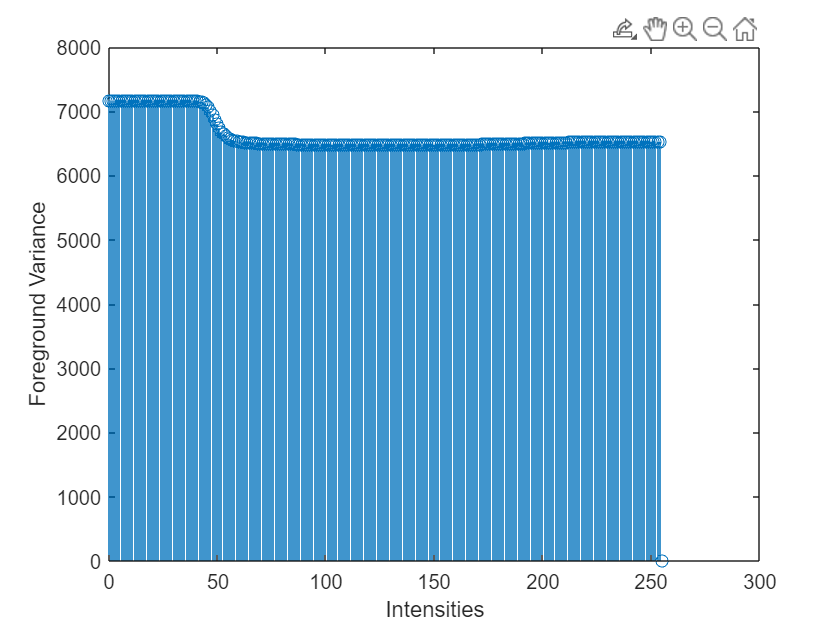


fv = zeros(256,1);
bv = zeros(256,1);
n_o = 0;
v_o = 0;
n_1 = 0;
v_1 = 0;
for i = 1:numImg
    [count, binLocations] = imhist(imgGray_arr{i});
    K = size(binLocations,1); %number of intensities
    %create mean luminance map to optimize run time
    [bgMLUT,fgMLUT]= MakeMeanTables(count, binLocations);
    for q = 1:K
        n_o = count(q) + n_o;
        v_o = v_o + power((q - bgMLUT(q)),2)*(count(q));
       
        if(n_o > 0)
            bv(q) = v_o/n_o;
        else
            bv(q) = -1;
        end        
    end

    for j = K-1:-1:1
        n_1 = count(j+1) + n_1;
        v_1 = v_1 + power(((j+1) - fgMLUT(K-j)),2)*(count(j+1));     
        if(n_1 > 0)
            fv(K-j) = v_1/n_1;
        else
            fv(K-j) = -1;
        end
    end
    figure
    stem(binLocations, bv, 'o')
    xlabel("Intensities")
    ylabel("Background Variance")

    figure
    stem(binLocations, fv, 'o')
    xlabel("Intensities")
    ylabel("Foreground Variance")
end